clc;clear;close all;

## 生成点

warning off

x = [-0.17263699	0.64102824	0.619187272	-0.169604585	-0.172290695	0.640753956	0.621242344	-0.170769907	-0.171522965	0.640246152	0.624506602	-0.171830944	-0.17083717	0.639008371	0.628110178	-0.171314854];
y = [0.018979904	0.142571117	0.609214188	0.276047528	-0.053249894	-0.032656584	0.438329502	0.208959385	-0.125595109	-0.206542736	0.267949915	0.140160375	-0.198118165	-0.378594402	0.096932468	0.069163785];
z = [-0.344388792	-0.670489171	0.286631526	0.1830114	-0.309268295	-0.580626074	0.372157833	0.220360057	-0.273244453	-0.491250982	0.458562455	0.258402244	-0.237311062	-0.402116506	0.545590665	0.294559421];


azimuth = 5.819341;
elevation = 1.582673;

P1 = [-0.25222006 0.655135248 -0.327650295];
P2 = [-0.249753513 -0.390018781 0.195244076];

% xx = [-0.166541824	-0.143183482	0.086083038	0.156469149	0.466618822	0.56448817	0.839716947	0.807804096];
% yy = [-0.049231542	0.233661612	-0.104236007	0.34170614	-0.091332629	0.380144412	0.261440943	0.017627278];
% zz = [0.365326614	-0.524532874	0.659289339	-0.829545167	0.707237057	-0.813472591	-0.522760129	0.428110448];
% PointFC = [xx;yy;zz];
Points = [x;y;z];
% Points = [Points,PointFC];

PAB = Points(:,5);

## 拟合圆柱

[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Points,P1,P2);

## A、B面点测试

numShengLu = 4;
phi = pi/4;

toff = zeros(1,2*numShengLu);
roff = zeros(1,2*numShengLu);

Ang = ShengLuJiaoJiSuan(numShengLu)

Ang =     0.9425    0.3142   -0.3142   -0.9425   -0.9425   -0.3142    0.3142    0.9425



[BianHao,PointTable_A_off,PointTable_B_off] = Calculat_A_and_B_Points_after_Offest2(Bottom_round_center1',Bottom_round_center2',MTaon',Mcenter',Mradial,PAB,phi,Ang,toff,roff)

E xyz: -0.712601, -0.622960, 0.322677
AngOring: -0.008775


BianHao =    -0.1301    0.1727    0.5438    0.8415    0.8331    0.5303    0.1592   -0.1384
    0.5571    0.8481    0.8448    0.5485   -0.4017   -0.6927   -0.6894   -0.3932
    0.1080    0.2025    0.2025    0.1080   -0.1980   -0.2926   -0.2926   -0.1980


PointTable_A_off =    -0.1356    0.1638    0.5349    0.8360    0.8386    0.5392    0.1681   -0.1329
   -0.0710   -0.1682   -0.1715   -0.0796    0.2264    0.3236    0.3269    0.2349
    0.4301    0.7238    0.7238    0.4301   -0.5201   -0.8138   -0.8138   -0.5201


PointTable_B_off =      8     1     7     2     6     3     5     4
     1     8     2     7     3     6     4     5


## 绘图验证

figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

% 绘制散点
scatter3(Points(1,:),Points(2,:),Points(3,:),5,"filled");
scatter3([P1(1),P2(1)],[P1(2),P2(2)],[P1(3),P2(3)],10,"filled");

PointTable_A_off = PointTable_A_off';
PointTable_B_off = PointTable_B_off';
% scatter3(PointTable_A_off(:,1),PointTable_A_off(:,2),PointTable_A_off(:,3),20,'filled','yellow')
% scatter3(PointTable_B_off(:,1),PointTable_B_off(:,2),PointTable_B_off(:,3),20,'filled','yellow')

## 复测数据

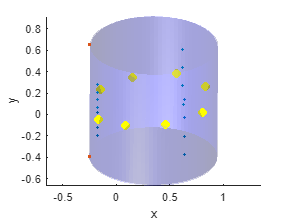

xx = [-0.166541824	-0.143183482	0.086083038	0.156469149	0.466618822	0.56448817	0.839716947	0.807804096];
yy = [-0.049231542	0.233661612	-0.104236007	0.34170614	-0.091332629	0.380144412	0.261440943	0.017627278];
zz = [0.365326614	-0.524532874	0.659289339	-0.829545167	0.707237057	-0.813472591	-0.522760129	0.428110448];
PointFC = [xx;yy;zz];

% scatter3(xx(1),yy(1),zz(1),50,'filled','yellow')
% scatter3(xx(2),yy(2),zz(2),50,'filled','yellow')
% scatter3(xx(3),yy(3),zz(3),50,'filled','green')
% scatter3(xx(4),yy(4),zz(4),50,'filled','green')

scatter3(xx,yy,zz,50,'filled','yellow')

## 计算距离

[Distance,theta,LTPY,TiC,Wquanzhong1,Wquanzhong2]=YuanXingFuCe(PointFC,numShengLu,Mcenter,MTaon,Mradial,phi)

Distance =     0.9340    1.5558    1.5951    0.9821


theta =     0.7892    0.8064    0.7975    0.8461


LTPY =     0.0012    0.0086    0.0104    0.0158


TiC =    -0.8446   -0.3852    0.2751    0.7869


Wquanzhong1 =     0.3001
    0.6151
    0.6273
    0.3880


Wquanzhong2 =     0.2968
    0.6143
    0.6312
    0.3804


LTPY*1000

ans =     1.1966    8.5997   10.3518   15.8340




% scatter3(Cross_point(:,1),Cross_point(:,2),Cross_point(:,3),50,'filled','black')